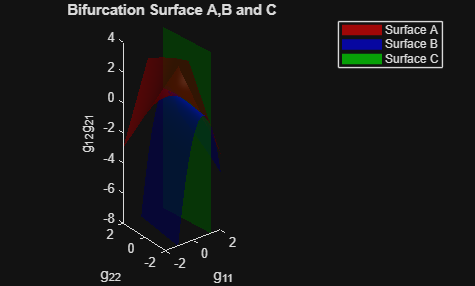

% create grid 
[g11,g22,g12g21] = meshgrid(-2:0.1:2, -2:0.1:2, -8:0.1:4);

% compute implicit volumes
F1 = (g11-1).*(g22-1) - g12g21;   % F1==0 is Surface A
F2 = ((0.2/0.02)*(g11-1)-(g22-1)).^2+4*(0.2/0.02)*g12g21;        % F2==0 is Surface B
F3 = (0.2/0.02)*(g11-1)+(g22-1);        % F3==0 is Surface C

figure;
% Surface A
fv1 = isosurface(g11,g22,g12g21,F1,0);
p1 = patch(fv1); hold on;
set(p1,'FaceColor','r','EdgeColor','none','FaceAlpha',0.6);
isonormals(g11,g22,g12g21,F1,p1);

% Surface B
fv2 = isosurface(g11,g22,g12g21,F2,0);
p2 = patch(fv2);
set(p2,'FaceColor','b','EdgeColor','none','FaceAlpha',0.6);
isonormals(g11,g22,g12g21,F2,p2);

% Surface C
fv3 = isosurface(g11,g22,g12g21,F3,0);
p3 = patch(fv3);
set(p3,'FaceColor','g','EdgeColor','none','FaceAlpha',0.6);
isonormals(g11,g22,g12g21,F3,p3);

% view and lighting
daspect([1 1 1]); axis tight; view(3);
camlight; lighting gouraud;
xlabel('g_{11}'); ylabel('g_{22}'); zlabel('g_{12}g_{21}');
title('Bifurcation Surface A,B and C');
legend([p1 p2 p3],{'Surface A','Surface B','Surface C'});